依赖[统一实验分析作图v17.2.0](https://github.com/ShanghaitechGuanjisongLab/Unified-Experimental-Analysis-and-Figuring/releases)

Naive hit miss 与 learned 的关系热图

预加载此脚本一次即可

DataSet=TransferLearning.FullCalcium;

QueryTable=UniExp.ReadQueryTable(TransferLearning.ProjectPath('查询表.xlsx'),'NaiveHitMiss');
Calcium=UniExp.NtatsCellReplenish(DataSet.QueryNTATS(QueryTable,UniExp.Flags.dFdF0,1:24,UniExp.Flags.Median));

Calcium=Calcium(any(Calcium.NTATS.Naive_light_water_hit,2),:);

取 Naive hit 和Learned前5%强细胞

Index5P=1:uint8(height(Calcium)/100);
[~,SortIndex]=sort(sum(Calcium.NTATS.Naive_light_water_hit,2),'descend');
[NaiveMean,NaiveSem]=MATLAB.DataFun.MeanSem(Calcium(SortIndex(Index5P),:).NTATS{:,:,["Naive_light_water_hit","Naive_light_water_miss","Learned_light_water"]},1);
[~,SortIndex]=sort(sum(Calcium.NTATS.Learned_light_water,2),'descend');
[LearnedMean,LearnedSem]=MATLAB.DataFun.MeanSem(Calcium(SortIndex(Index5P),:).NTATS{:,:,["Naive_light_water_hit","Naive_light_water_miss","Learned_light_water"]},1);
SubTitles=["Naive light water hit","Naive light water miss","Learned light water"];

Xs=linspace(-3,12,size(NaiveMean,2))';

作三种条件下的曲线

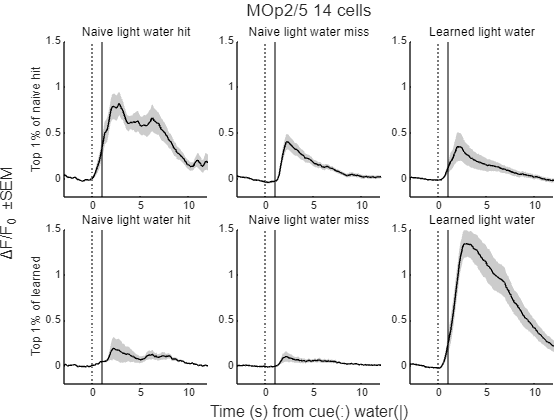

figure;
Layout=tiledlayout(2,3,TileSpacing='tight',Padding='tight');
Axes=gobjects(2,3);
for A=1:3
	Axes(1,A)=nexttile;
	MATLAB.Graphics.MultiShadowedLines(NaiveMean(:,:,A)',NaiveSem(:,:,A)',X=Xs);
	xline(0,':k');
	xline(1,'-k');
	title(SubTitles(A));
end
for A=1:3
	Axes(2,A)=nexttile;
	MATLAB.Graphics.MultiShadowedLines(LearnedMean(:,:,A)',LearnedSem(:,:,A)',X=Xs);
	xline(0,':k');
	xline(1,'-k');
	title(SubTitles(A));
end
ylabel(Axes(1,1),'Top 1% of naive hit');
ylabel(Axes(2,1),'Top 1% of learned');
xlabel(Layout,'Time (s) from cue(:) water(|)');
ylabel(Layout,'ΔF/F_0 ±SEM');
title(Layout,sprintf('MOp2/5 %u cells',numel(Index5P)));
MATLAB.UnifyYLims(Axes);
print(TransferLearning.ProjectPath('NaiveHitMissCurve.svg'),'-dsvg');